%save("MotorX_PID_corrected.mat")

%load MotorX_PID.mat


%t_X_PID = out.tout;
%input_X_PID = out.simout.Data;
%error_X_PID = out.simout1.Data;
%CE_X_PID = out.simout2.Data;
%offset = -0.5;

offset = -0.5000

%output_X_PID = out.simout3.Data-offset;

%GX = 1.72;
%CE_X_PID = (11.4/255)*GX*CE_X_PID;

load MotorX_PID_corrected.mat

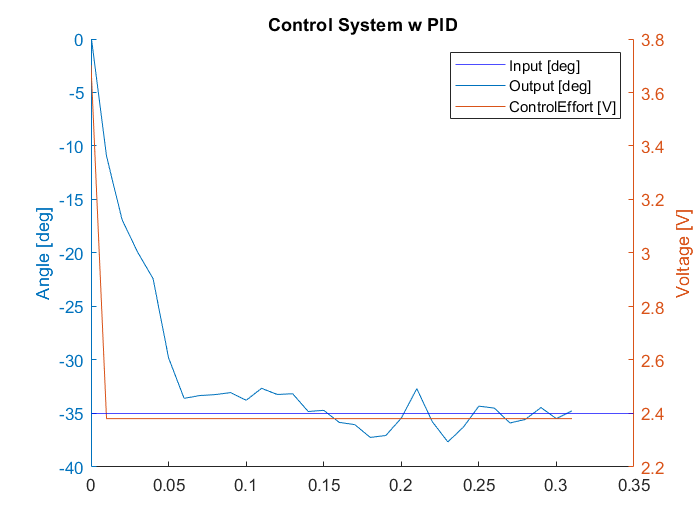

clf;
hold on
yyaxis left
yline(-35,'b')
plot(t_X_PID,output_X_PID)
ylabel('Angle [deg]')
ylim([-40 0])


yyaxis right
plot(t_X_PID,CE_X_PID)
ylabel('Voltage [V]')
title('Control System w PID')
legend('Input [deg]','Output [deg]','ControlEffort [V]')

hold off